# LME Tutorial 2: Non-linear dependence

## Global parameters

clear % clear workspace
close all % close figures
% seed = 'shuffle'; % random seed
seed = 0;
rng(seed); % set random seed
N = 100; % number of subjects

## Non-linear dependence on initial weight

Measurement error

eps = 0.01;

Weight variability

delta = 5;

Initial weight distribution

Weight1_true = 70 + delta*randn(N,1);
Weight1 = Weight1_true + eps*randn(N,1);

Final weight

Weight2 = Weight1_true + 0.1 + (1/mean(Weight1_true)^2)*(Weight1_true-50).^2 + eps*randn(N,1);

Weight gain as quadratic function of initial weight

gain = vpa(expand(0.1 + 1/mean(Weight1_true)^2*(sym('InitialWeight')-50)^2),4)

$$gain = 0.0002023\,{\mathrm{InitialWeight}}^{2}-0.02023\,\mathrm{InitialWeight}+0.6057$$

Create Dataset

Subject = categorical((1:N)');
InitialWeight = Weight1;
Gain = Weight2-Weight1;

Data = table;
Data.Subject = Subject;
Data.InitialWeight = InitialWeight;
Data.FinalWeight = Weight2;
Data.Gain = Gain;
% convert to categorical
Data.Subject = categorical(Data.Subject);
% sort by subject
Data = sortrows(Data,{'Subject'});
head(Data)

ans = 8×4 table
    Subject     InitialWeight        FinalWeight             Gain       
    _______    ________________    ________________    _________________

       1       70.9131780838948    71.0974758512824    0.184297767387619
       2       68.7039028752864    68.8817686658539    0.177865790567481
       3       63.2282555221329    63.3617459004179    0.133490378284918
       4       64.1956755916245    64.3671652105193    0.171489618894825
       5       66.1780106486651    66.3322296428743    0.154218994209231
       6        68.730772927623    68.9220126354927    0.191239707869684
       7       61.7554596567739    61.8736815021875    0.118221845413601
       8       69.0728357651788    69.2699563810392    0.197120615860428


% save data table to Excel file
writetable(Data,'Chocolate_LM2.xlsx');

Histogr am with Gaussian fit

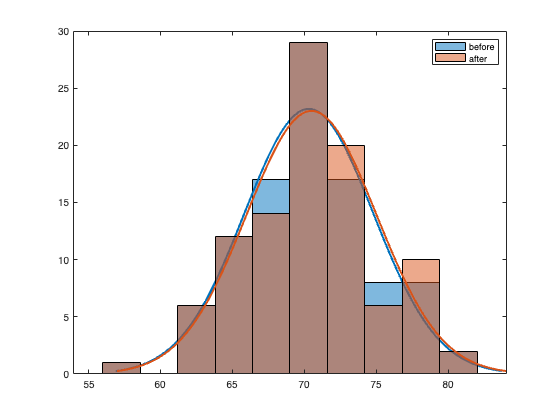

figure
cmap = colormap('lines');
h1 = histfit(Weight1);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Weight2);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'before','after'})
hold off

Gain versus initial weight

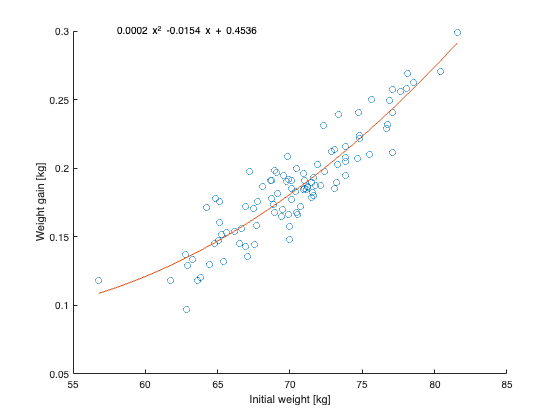

scatter(InitialWeight,Gain)
hold on
a = polyfit(InitialWeight,Gain,2);
x1 = linspace(min(InitialWeight),max(InitialWeight));
y1 = polyval(a,x1);
plot(x1,y1);
text(0.1,1,sprintf('%.4f x^2 %.4f x + %.4f',a(1),a(2),a(3)),'Units','normalized');
hold off
xlabel('Initial weight [kg]');
ylabel('Weight gain [kg]');

## T-test

[~,p] = ttest2(Weight1,Weight2) % unpaired

p =    0.769081935692309


[~,p] = ttest(Weight1,Weight2) % paired

p =      3.040789928969526e-71


t-test on gain

[~,p] = ttest(Gain)

p =      3.040789928969526e-71


## Linear Model

formula = 'Gain ~ InitialWeight'

formula = 'Gain ~ InitialWeight'

mdl1 = fitlme(Data,formula);
stats1 = anova(mdl1) 

stats1 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                     FStat               DF1    DF2    pValue              
    {'(Intercept)'  }        198.876988550028    1      98     2.53470661768258e-25
    {'InitialWeight'}        463.645700626752    1      98     6.19957887949195e-39


## Quadratic effect term

formula = 'Gain ~ InitialWeight^2'

formula = 'Gain ~ InitialWeight^2'

mdl2 = fitlme(Data,formula);
stats2 = anova(mdl2) 

stats2 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                       FStat               DF1    DF2    pValue             
    {'(Intercept)'    }        2.96146340397347    1      97      0.0884590121442238
    {'InitialWeight'  }        4.21951073983875    1      97      0.0426516898394972
    {'InitialWeight^2'}        9.52195272391883    1      97     0.00264604529998533


Compare models

RSquared1 = mdl1.Rsquared.Ordinary

RSquared1 =    0.822583584175647


RSquared2 = mdl2.Rsquared.Ordinary

RSquared2 =    0.838008352287813


compare(mdl1,mdl2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue             
    mdl1     3     -537.773259013159    -529.957748455195     271.88662950658                                                      
    mdl2     4     -544.868741480576    -534.448060736623    276.434370740288    9.09548246741667    1          0.00256241608631502


## Final weight as dependent variable

formula = 'FinalWeight ~ InitialWeight^2'

formula = 'FinalWeight ~ InitialWeight^2'

mdl3 = fitlme(Data,formula);
stats3 = anova(mdl3) 

stats3 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                       FStat               DF1    DF2    pValue               
    {'(Intercept)'    }        2.96146341873853    1      97        0.0884590113620736
    {'InitialWeight'  }        17191.9962493524    1      97     5.43533935940444e-111
    {'InitialWeight^2'}        9.52195275046802    1      97       0.00264604526516947


RSquared3 = mdl3.Rsquared.Ordinary

RSquared3 =    0.999988435516403


Advantage: dependence of (absolute) weight on other factors can be tested

load('randstate');
rng(randstate); % set random seed

Nm = 40;
Weight1m_true = 78 + delta*randn(Nm,1);
Weight1m = Weight1m_true + eps*randn(Nm,1);
Weight2m = Weight1m_true + 0.1 + (1/mean(Weight1m_true)^2)*(Weight1m_true-50).^2 + eps*randn(Nm,1);

Nf = 60;
Weight1f_true = 62 + delta*randn(Nf,1);
Weight1f = Weight1f_true + eps*randn(Nf,1);
Weight2f = Weight1f_true + 0.1 + (1/mean(Weight1f_true)^2)*(Weight1f_true-50).^2 + eps*randn(Nf,1);

Data2 = table;

Subjectm = categorical((1:Nm)');
Genderm = repmat({'m'},Nm,1);
InitialWeightm = Weight1m;
FinalWeightm = Weight2m;
Gainm = Weight2m-Weight1m;
Subjectf = categorical((1:Nf)');
Genderf = repmat({'f'},Nf,1);
InitialWeightf = Weight1f;
FinalWeightf = Weight2f;
Gainf = Weight2f-Weight1f;
Subject = [Subjectm;Subjectf];
Gender = [Genderm;Genderf];
InitialWeight = [InitialWeightm;InitialWeightf];
FinalWeight = [FinalWeightm;FinalWeightf];
Gain = [Gainm;Gainf];

Data2.Subject = Subject;
Data2.Gender = Gender;
Data2.InitialWeight = InitialWeight;
Data2.FinalWeight = FinalWeight;
Data2.Gain = Gain;
% convert to categorical
Data2.Subject = categorical(Data2.Subject);
Data2.Gender = categorical(Data2.Gender);
% sort by subject
Data2 = sortrows(Data2,{'Subject'});
head(Data2)

ans = 8×5 table
    Subject    Gender     InitialWeight        FinalWeight             Gain       
    _______    ______    ________________    ________________    _________________

       1         m       80.3693976141869     80.621483753487    0.252086139300118
       1         f       64.0840345110296    64.2404859540485    0.156451443018909
       2         m       85.0494331089498    85.3549990783397    0.305565969389903
       2         f        63.734717232236    63.8922458353153    0.157528603079335
       3         m       78.0957881436527    78.3468422950365     0.25105415138384
       3         f       63.7369088183474    63.9014583855063    0.164549567158922
       4         m       77.7635352297956     77.980138685455    0.216603455659396
       4         f       58.3410727941238    58.4688541676649     

Without gender dependence

formula = 'FinalWeight ~ InitialWeight^2'

formula = 'FinalWeight ~ InitialWeight^2'

mdl4 = fitlme(Data2,formula);
stats4 = anova(mdl4) 

stats4 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                       FStat               DF1    DF2    pValue               
    {'(Intercept)'    }        5.83934921930621    1      97        0.0175419361843245
    {'InitialWeight'  }        124287.062541931    1      97     1.47890485107077e-152
    {'InitialWeight^2'}        23.8038197664734    1      97      4.18130346021405e-06


RSquared4 = mdl4.Rsquared.Ordinary

RSquared4 =    0.999996567388742


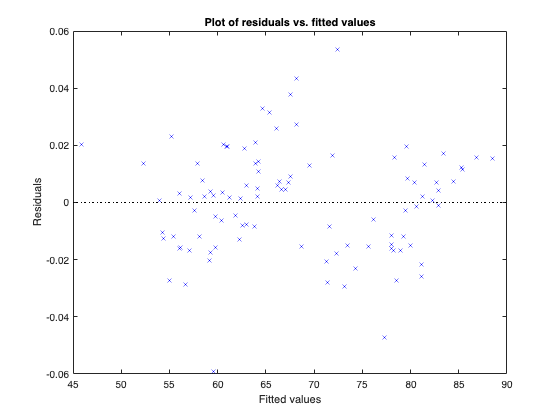

plotResiduals(mdl4,'fitted');

With gender dependence on gender

formula = 'FinalWeight ~ Gender*InitialWeight^2'

formula = 'FinalWeight ~ Gender*InitialWeight^2'

mdl5 = fitlme(Data2,formula)

mdl5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             100
    Fixed effects coefficients           6
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    FinalWeight ~ 1 + Gender*InitialWeight + InitialWeight^2 + Gender:(InitialWeight^2)

Model fit statistics:
    AIC                  BIC                LogLikelihood       Deviance         
    -556.446098823316    -538.2099075214    285.223049411658    -570.446098823316

Fixed effects coefficients (95% CIs):
    Name                                Estimate                 SE                      tStat                  DF    pValue                   Lower                    Upper               
    {'(Intercept)'             }            0.836460023400497       0.179193117408409       4.66792494878067    94     1.00868429576354e-05        0.480667888164948  

stats5 = anova(mdl5) 

stats5 =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                FStat                  DF1    DF2    pValue               
    {'(Intercept)'             }            21.789523327449    1      94      1.00868429576354e-05
    {'Gender'                  }          0.663956417158765    1      94         0.417226307380067
    {'InitialWeight'           }           26899.0615058879    1      94     2.41613477968941e-117
    {'Gender:InitialWeight'    }          0.224956107519935    1      94         0.636389222020646
    {'InitialWeight^2'         }           36.2509246305727    1      94      3.33596176780826e-08
    {'Gender:(InitialWeight^2)'}        0.00034427689507501    1      94         0.985235668102248


RSquared5 = mdl5.Rsquared.Ordinary

RSquared5 =    0.999998013836194


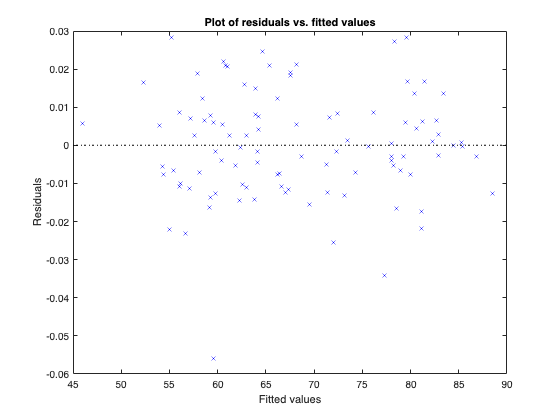

plotResiduals(mdl5,'fitted');

Remove outliers

outliers = isoutlier(residuals(mdl5));
fprintf('Removed %d outlier(s) from data',sum(outliers))

Removed 1 outlier(s) from data

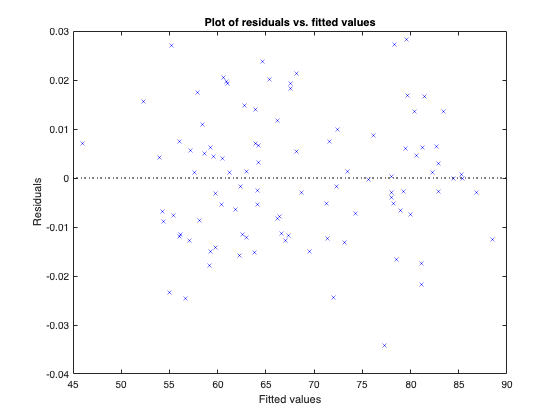

mdl5 = fitlme(Data2,formula,'Exclude',outliers);
plotResiduals(mdl5,'fitted');

Compare models

compare(mdl4,mdl5)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC                  BIC                  LogLik              LRStat              deltaDF    pValue              
    mdl4     4     -507.734475949727    -497.313795205775    257.867237974863                                                       
    mdl5     7      -567.45889303496    -549.293054084018     290.72944651748    65.7244170852329    3          3.50830475781549e-14
